## Intuition for pole analysis

Let us consider the following transfer funciton with a single pole 

syms s a 
H(s) = 1/(s-a)

$$H(s) = -\frac{1}{a-s}$$

What is the pole? 

Now, let's look at its impulse response 

syms t 
h(t) = ilaplace(H)

$$h(t) = {\mathrm{e}}^{a\,t}$$

Do you see any relationship between the pole and the impulse response?  Think about what will happen for postive and negative values for $a$. 

Let's explore this scenario for different values of $a$ 

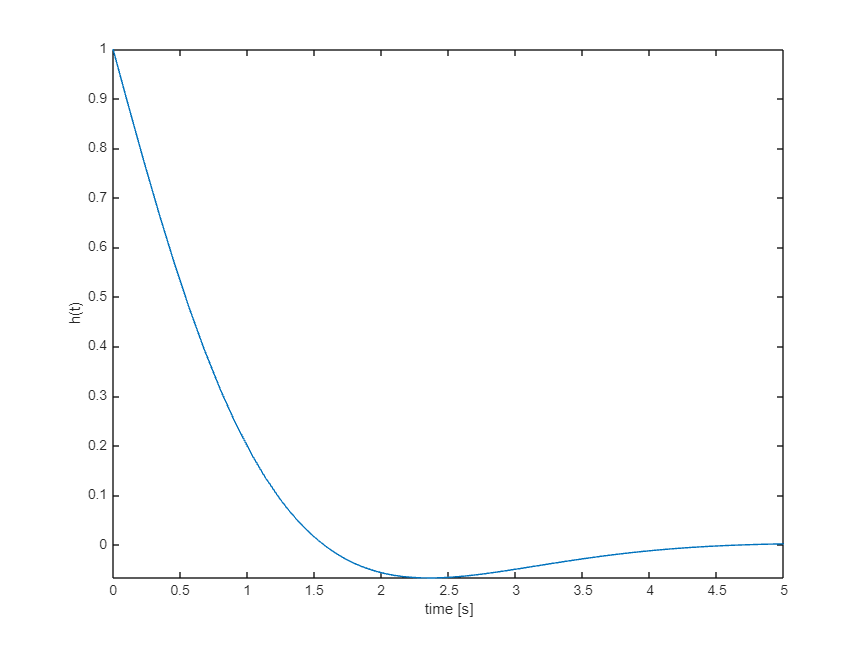

clear a
a = "-1+1j";
h(t) = exp(a*t);
fplot(real(h(t)),[0,5])
xlabel('time [s]') 
ylabel('h(t)')

What if there are 2 poles? 

syms s a b
H(s) = 1/((s-a)*(s-b))

$$H(s) = \frac{1}{\left(a-s\right)\,\left(b-s\right)}$$

What are the poles in this case? 

h(t) = ilaplace(H)

$$h(t) = \frac{{\mathrm{e}}^{a\,t}}{a-b}-\frac{{\mathrm{e}}^{b\,t}}{a-b}$$

In this case, we see a sum of exponentials which coefficients in the power determined by the poles. 